# Making Cool Sounds with MATLAB (Like an Echo Effect!)

This assignment is all about using a powerful tool called **convolution** in MATLAB to play with sound waves and create fun effects. It's like mixing colors but with sounds!

While this exercise focuses on sound, you can actually use convolution for many other things in engineering and science. But for now, get ready to hear some cool sonic transformations!

**Here's what you need:**

- Your trusted computer with MATLAB.

- A pair of headphones or speakers (optional but highly recommended) to hear the awesome sounds you create.

**Why headphones/speakers?**

Well, we'll be using MATLAB to play with sound and actually hear the results! MATLAB has built-in functions like `sound` and `soundsc` that let you play sounds straight from your computer. Just type `help sound` in MATLAB to learn more about these cool features.

## Loading the Data

To begin, acquire the speech waveform from the class website named "echo.mat." Ensure that you save this data file to the current working directory of MATLAB. Follow the steps below to load the data using the load command. This process is crucial for our subsequent analyses.

- Save "echo.mat" to your MATLAB's current working directory.

- Open MATLAB on your computer.

- Type the following command in the MATLAB command prompt:

load echo.mat

This command will load two essential variables into the MATLAB workspace:

- `xx`: The speech waveform

- `fs`: The sampling frequency of the speech waveform

whos

  Name          Size             Bytes  Class     Attributes

  fs            1x1                  8  double              
  xx        16001x1             128008  double              



The `whos` command displays information about the variables  in the current workspace, including their names, sizes, and data types. 

## Listening to the Speech Waveform

Given that you possess headphones, speakers, or access to the internal  speakers of your PC, you can audibly perceive the speech waveform using  the `sound` or `soundsc` functions in MATLAB. The prescribed syntax for these functions is as follows:

sound(xx, fs)

Error using sound
Not enough input arguments.

Executing this command will result in the playback of the speech  waveform through your computer's sound card. It's worth noting that the  only distinction between `sound` and `soundsc` lies in the scaling behavior of the waveform. Specifically, `soundsc` is designed to scale the waveform optimally, maximizing volume without inducing clipping. 

## Plotting the Speech Waveform

Generate a graphical representation of the speech waveform by plotting it against time, rather than sample values. This entails converting the sample values to their respective time values utilizing the provided sampling frequency. Employ the `plot` function for this purpose, as opposed to the `stem` function, given the transformation of the x-axis to represent time instead of sample values.

Ensure that all plots are appropriately labeled to facilitate a clear interpretation of the visualizations. This meticulous approach guarantees a comprehensive understanding of the speech waveform's temporal characteristics.

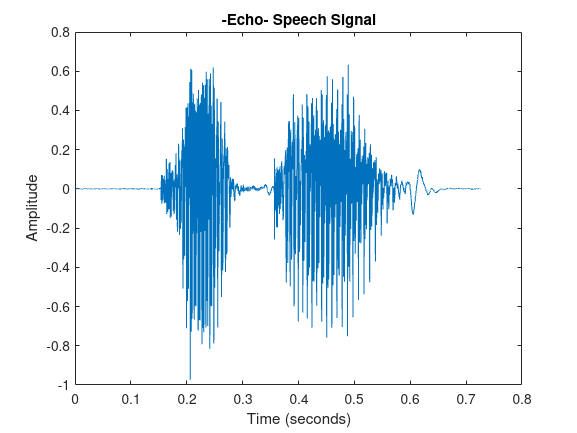

% Calculate time vector
time = (0:length(xx)-1) / fs;
% Plotting the Speech Waveform
figure;
plot(time, xx);
title('-Echo- Speech Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');

## Create a System Impulse Response

Create a system that mimics an "echo" effect for the original speech waveform in discrete-time. The system should allow the current input value to pass through without attenuation (gain of 1). Additionally, it should incorporate a delayed version of the input signal that is attenuated by a factor of 4 (i.e., the echo should be 1/4 the size of the original signal and delayed by one second). In simpler terms, the output of the system will include both the unattenuated present signal and a delayed, attenuated version.

Imagine standing on one mountain and shouting towards another mountain – your voice reaches your ears instantly, and a moment later, you hear the echo from the distant mountain. In MATLAB, this translates to creating an impulse response that captures this behavior.

Consider the following hints:

- Determine the number of samples in one second of time.

- When creating the impulse response, think about what the input should be. You're essentially setting up a scenario where the system responds to the immediate sound and the delayed, attenuated echo.

% Parameters
delay_seconds = 1;          % One-second delay
attenuation_factor = 1/4;   % Attenuation factor for the echo

% Calculate delay in samples
delay_samples = round(delay_seconds * fs);

% Create the impulse response
impulse_response = zeros(1, delay_samples + 1);
impulse_response(1) = 1;             % Unattenuated present value
impulse_response(delay_samples + 1) = attenuation_factor;  % Attenuated delayed value

% Apply the system impulse response using convolution (assuming you have loaded the data with variables xx and fs)
output_waveform = conv(xx, impulse_response, 'full');

% Listening to the Output Waveform with Echo
soundsc(output_waveform, fs);

Not enough input arguments.

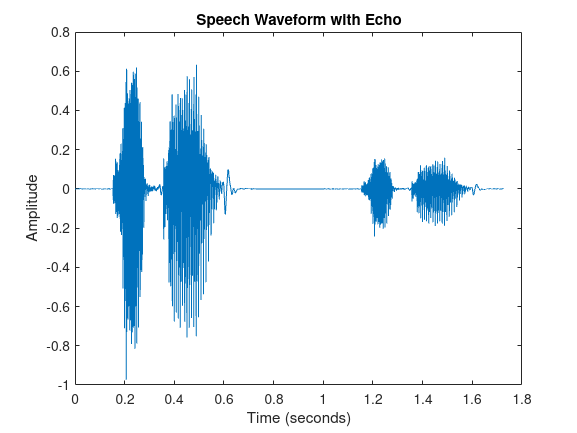

% Plotting the Output Waveform
output_time = (0:length(output_waveform)-1) / fs; % Time vector for output
figure;
plot(output_time, output_waveform);
title('Speech Waveform with Echo');
xlabel('Time (seconds)');
ylabel('Amplitude');

## Exercise

Develop a function capable of handling four essential parameters:

- Input signal

- Time delay (in seconds)

- Attenuation factor of the echo

- Sampling frequency of the input signal

The function structure is exemplified as follows:

[output] = digitaldelay(input, timedelay, echoattenuation, samplingfreq);

This function serves the purpose of passing both the immediate value of the input signal and producing an echo attenuated by a specified factor. This effect is commonly employed in music, similar to providing a brief delay (approximately 0.1 seconds) to enhance the richness of a guitar's sound. The outcome often emulates the impression of multiple guitars playing simultaneously.

Furthermore, the function is designed to offer flexibility, enabling adjustments to both the time delay and the attenuation of the echo. This versatility allows users to explore various settings, creating diverse auditory experiences.

Now use this function to create a guitar effect known as digital delay on guitar.mat file provided.

Remember, the function should be written only at the bottom of a live script file. Also, play around with different values of time delay and attenuation.

load guitar.mat
whos

  Name           Size              Bytes  Class     Attributes

  fs             1x1                   8  double              
  xx        401146x1             3209168  double              



soundsc(xx,fs)

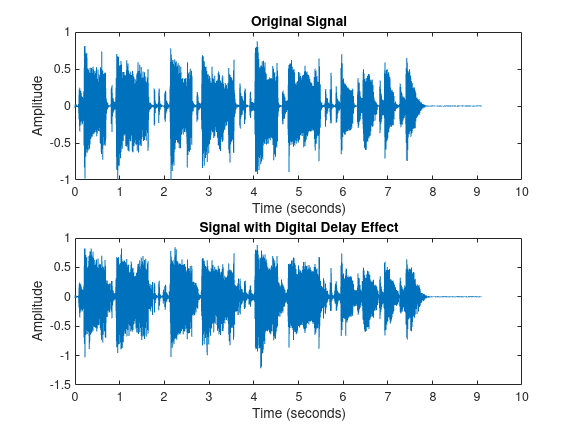

timedelay = 0.1;          % Time delay in seconds
echoattenuation = 0.5;    % Attenuation factor of the echo

% Call the digitaldelay function
output_signal = digitaldelay(xx, timedelay, echoattenuation, fs);

% Play the guitar sound with digital delay effect
soundsc(output_signal,fs)

% Plot the input and output signals
time = (0:length(xx)-1) / fs; % Time vector
figure;
subplot(2,1,1);
plot(time, xx);
title('Original Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');

subplot(2,1,2);
plot(time, output_signal);
title('Signal with Digital Delay Effect');
xlabel('Time (seconds)');
ylabel('Amplitude');

function output = digitaldelay(input, timedelay, echoattenuation, samplingfreq)
    % Validate input arguments
    if nargin ~= 4
        error('Four input arguments are required.');
    end
    
    % Your code here
end
